## 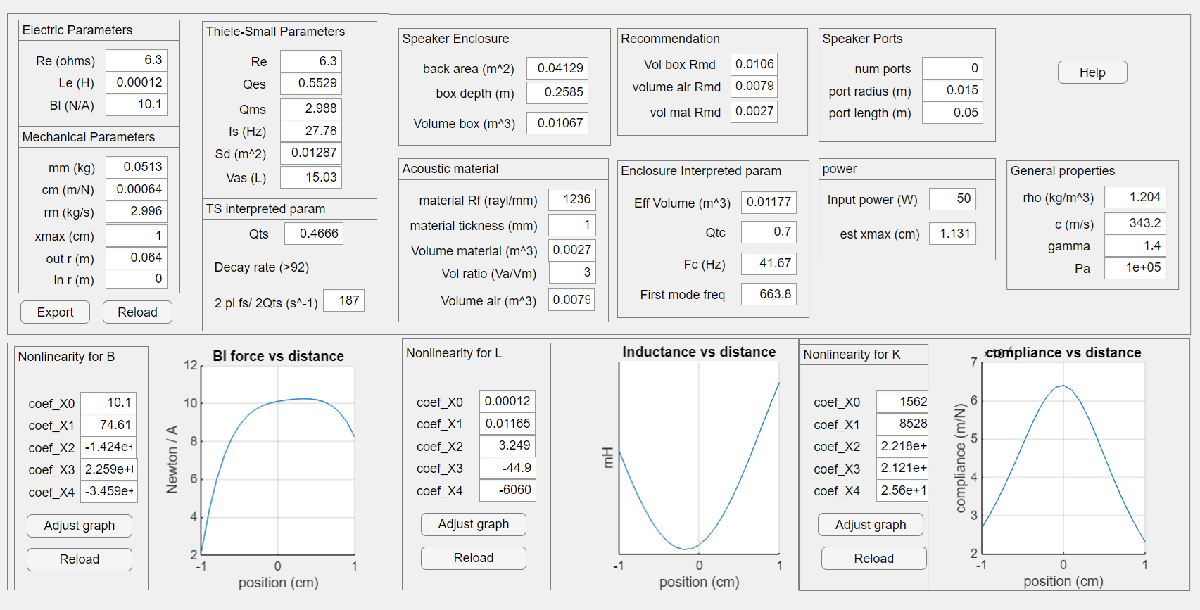

## Parameters

### Electrical Parameters

Re -- The resistance in the electric circuit.  This includes the resistance in the coil.

Le -- This is the inductance of the coil.  Note that the value here is displacement position depended.  The value here is the constant part of the polynomial in the nonlinearity curve (Ldxx(1)).  That is, if there is no nonlinearity then Ldxx would be a straight line and in such a case Ldxx would be simply Le.  Note that the value from the datasheet is usually higher (10x) than actual usage in the model.  The model used is an approximation of the real system with some intricate dependencies omitted.

Bl -- The force factor that relates the current in the coil to the mechanical force to move the mechanical part.  Note that this factor is displacement position dependent.  The value here is the constant part of the polynomial in the nonlinearity curve (Blxx(1)). That is, if there is no nonlinearity then Blxx would be a straight line and in such as case Blxx would be Bl.

### Mechanical Parameters

mm --  This is the moving mass, the weight of the moving parts that includes the coil, the cone etc.

cm --  The suspension compliance.  The suspension serves the purpose of fixing the voice coil in a defined resting position.  In a linear model this is modeled as a spring with the spring constant being the inverse of the compliance.  In a nonlinear model this value is the inverse of the constant value in Kdxx.

rm -- mechanical resistance, this resistance constitude to the mechanical loss due to friction of the moving parts.

xmax -- the maximum displacement of the cone relative to its resting position.  In our model this value is used in setting the range of the x-axis in the nonlinearity graphs (Blxx, Ldxx, Ldxx).  In some loudspeaker specifications this is the maximum linear excursion.

out r -- the radius of the cone from the center to the edge.

in r -- the radius of the cone from the center to the moving coil.

### Thiele-Small Parameters

These are parameters that are published in the specification of loudspeakers drivers.  It is a set of electromechanical parameters that specifies the low frequency performance of the driver.

Re -- The resistance in the electric circuit.  This includes the resistance in the coil. This value is the same as the one in the electrical parameter section.

Qes -- A unitless value that quantifies the electrical damping of the loudspeaker.

Qms --  A unitless value that quantifies the mechanical damping of the loudspeaker.

fs -- The resonance frequency of the loudspeaker driver.  It is contributed by the moving mass and the suspension compliance.

Sd -- The area of the diaphragm (cone) of the loudspeaker.

Vas --  The equivalent compliance volume, it is the compliance of the loudspeaker driver being represented as an equivalent volume of air.

### TS interpreted Parameters

Qts -- A unitless value that quantifies the combined damping of the electrical and the mechanical sections.

Decay rate -- A measure of how fast the "stored" energy in the loudspeaker is being relased.  It is preferred to have a value of larger than 92.

### Enclosure -- Box size

back area (Sm) -- the area at the back of the speaker box.

Box depth (boxDepth) -- the depth or length of the box.

Volume box (Vbox) -- volume of the box.  It is equal to Sm*boxDepth.

### Enclosure -- Acoustic material

Acoustic material is to be placed inside the enclosure to absorb part of the air flow.  This would result in an effective enclosure box (Veff) that is slightly bigger than the actual size, Vbox.

Rf -- the flow resistance of the acoustic material to be placed inside the enclosure.  Note that if we simply want to assume a material that gives the impedance of free space then use a value of  approximately 1236 = 412*3.  In this case the thickness of the material would need to be set as 1.

material thickness (mthick) -- the thickness of the acoustic material.  As mentioned in (Rf) set this value to 1 when needed to assume a free space resistance.

Volume of the acoustic material (Vm) -- Note that the volume of air (Va) plus Vm would equal to the volume of the box (Vbox).

Volume ratio (vratio) -- this is the ratio of Va to Vm.  The air volume to acoustic material volume.

Volume air (Va) -- this is the volume of air inside the enclosure.  Note that if there is no acoustic material then Va would be the same as Vbox.

### Enclosure -- Recommended params

Vol box Rmd (VboxRmd) -- the recommended volume of the box.  Please set Vbox to this value in order to apply this value.

Volume air Rmd (VaRmd) -- the recommended volume of air inside the box.  Please set Va to this value in order to apply this value.

vol mat Rmd (VmRmd) -- the recommended volume of the acoustic material inside the box.  Please set Vm to this value in order to apply this value.

### Enclosure -- interpreted parameters

Eff Volume (Veff) -- the effective volume of the enclosure box.

Qtc -- A unitless value that quantifies the combined damping of the whole loudspeaker including the enclosing box.

Fc -- The target resonant frequency of the whole loudspeaker including the enclosing box.

First mode frequency -- estimated frequency of the vibration mode coming from the back of the speaker box. 

### Enclosure -- ports

num ports -- number of ports (holes) in the loudspeaker enclosure.  This value is set to zero for now since the speaker enclosure model with ports are not yet ready.

port radius -- the radius of the port (hole).

port length -- this is intended for enclosures with extended tube-like transmission line at the port hole.  This model is not yet ready.

### Power supply

Input power -- the intended input power of the loudspeaker.  This is the value at the output of the amplifier.  This input power would be used to estimate the maximum excursion of the loudspeaker.

est xmax -- The estimated maximum excursion of the loudspeaker based on the input power.

## General properties

rho -- density of air, this value is temperature dependent, 1.2041 kg/m^3  at 20 C, 1.1839 at 25 C.

c -- speed of sound, this value is temperature dependent, 343.3 m/s at 20 C, 346.3 at 25 C.  Actually, it is also hyumidity and pressure dependent but these factors are of lesser effects.

gamma -- The ratio of specific heat of the gas at constant pressure to the specific heat at constant volume for the gas.  One can think of it as gaseous compression ratio, for air it is 1.4.

Pa -- atmospheric pressure in Pa

## Export and Reload Param-panel

These buttons resides in the "Parameter panel" application.

Export -- click on this button would export all the parameters being displayed in the parameter panel to the MATLAB workspace.  It is only after the parameters have been exported to the workspace that they can be taken into effect and be used in the simulations.

Reload -- Users can change the parameters in the parameter panel at will and they will not be applicable in the model simulations unless they are exported to the workspace.  When the "reload" is clicked, all the displayed parameters will be removed and the values will be retrieved from the workspace. 

## Adjusting the nonlinearity curves

Only the first coefficient in each of the curves can be modified from the param panel.  In the nonlinearity for B curve the coef_X0 is the Bl value in the electric parameter.  In the nonlinearity for L curve the coef_X0 is the Le value in the electric parameter.  In the nonlinearity for K curve the coef_X0 value is the 1/cm value in the mechical parameter.

Adjust graph -- click on this button would open up the application Adjust-Graph, paramAdjustApp.mlapp.  Each nonlinearity curve would have its own adjustment app button.  The paramAdjustApp would allow user to adjust the coefficients.  Note that after modifying the values in the paramAdjustApp the user has to click the export button in the paramAdjustApp in order for the changed coefficients be available in the workspace.  At this point the user should reload the parameters in the param panel in order to see the effect of the coefficient change on other parameters.

Reload -- click on this button would retrieve the coefficients from the workspace to the parameter panel and update the graph displayed.  Each nonlinearity curve has its own reload button.

## Table of Parameter dependencies

boxRL = [box.rear_R box.rear_M] -- the box resistance and inductance

boxC = box.rear_C -- the box capacitance

Ram, Cam, Qmb -- internal variables

x = cannot be modified


% varNames = {'Re','Le','Bl','mm','cm','rm','xmax','out_r','in_r','Qes','Qms',...
%     'fs','Sd','Vas','Qts','decayRate','bk area','box depth','Vbox',...
%     'Rf','mthick','Vm','vratio','Va','VboxRmd','VaRmd','VmRmd','Veff','Qtc','Fc','ffreqM',...
%     'numPort','portR','portL','inPower','est_xmax','rho','c','gamma','Pa'};

Re = "Qes Qts decayRate fc boxRL Rab Qmb Qtc fc";
Le = "Ldxx boxRL Rab Qmb Qtc fc";
Bl = "Qes Qts decayRate Blxx boxRL Qmb Qtc fc";
mm = "Qms fs Qts decayRate boxRL Qmb Qtc fc";
cm = "Vas Qes Qms fs Kdxx boxRL Qmb Qtc fc";
rm = "Qms Qts decayRate boxRL Qmb Qtc fc";
xmax = "nonlinearity curves";
out_r = "Sd Vas fc boxC Qmb Qtc";
in_r = "Sd Vas fc boxC Qmb Qtc";
Qes = "Bl Qes Qts decayRate Blxx fc boxRL Qmb Qtc";
Qms = "rm Qms Qts decayRate fc boxRL Qmb Qtc";
fs = "cm Vas Qes Qms decayRate Kdxx fc boxRL Qmb Qtc";
Sd = "Vas boxC";
Vas = "x";
Qts = "x";
decayRate = "x";

Sm = "Vbox Vm vratio Ram Cam Qmb Qtc fc"; 
boxDepth = "Vbox Va vratio Caa firstModeFreq Veff Qtc fc";
Vbox = "boxDepth Va vratio Caa firstModeFreq Veff Qtc fc";

Rf = "Ram Rab Qmb Qtc fc ";
mthick = "Ram Rab Vm vratio Cam Qmb Veff Va Caa Qtc fc";
Vm = "mthick Va Ram vratio Cam Qmb Veff Va Caa Qtc fc";
vratio = "mthick Vm Ram Rab Cam Qmb Veff Va Caa Qtc fc";
Va = "Vm vratio mthick Ram Rab Cam Qmb Veff Caa Qtc fc"; 

VboxRmd = "x";
VaRmd = "x";
VmRmd = "x";

Veff = "x";
Qtc = "Fc vol_Rmd Va_Rmd Vm_Rmd";
Fc = "Qtc vol_Rmd Va_Rmd Vm_Rmd";
firstModeFreq = "boxDepth Vbox Va vratio Caa firstModeFreq Veff";

inPower = "est_Xmax";
est_xmax = "x";

numPort = "x"; % set to 0,
portR = "x";
portL = "x";

rho = "Caa Rab Qmb VaRmd";
c = "Qmb VaRmd firstModeFreq"; 
gamma = "Mab Caa VaRmd Veff"; 
Pa = "Cam Cab"; 


TT = table(Re,Le,Bl,mm,cm,rm,xmax,out_r,in_r,Qes,Qms,fs,Sd,Vas,Qts,decayRate,...
    Sm, boxDepth, Vbox,Rf,mthick,Vm,vratio,Va,VboxRmd,VaRmd,...
    VmRmd,Veff,Qtc,Fc,firstModeFreq,inPower,est_xmax,numPort,portR,portL,rho,c,gamma,Pa);
TTT = rows2vars(TT);
TTT.Properties.VariableNames = {'Var','dependencies'};
TTT

TTT = 40×2 table
         Var                           dependencies                  
    _____________    ________________________________________________

    {'Re'       }    "Qes Qts decayRate fc boxRL Rab Qmb Qtc fc"     
    {'Le'       }    "Ldxx boxRL Rab Qmb Qtc fc"                     
    {'Bl'       }    "Qes Qts decayRate Blxx boxRL Qmb Qtc fc"       
    {'mm'       }    "Qms fs Qts decayRate boxRL Qmb Qtc fc"         
    {'cm'       }    "Vas Qes Qms fs Kdxx boxRL Qmb Qtc fc"          
    {'rm'       }    "Qms Qts decayRate boxRL Qmb Qtc fc"            
    {'xmax'     }    "nonlinearity curves"                           
    {'out_r'    }    "Sd Vas fc boxC Qmb Qtc"                        
    {'in_r'     }    "Sd Vas fc boxC Qmb Qtc"                        
    {'Qes'      }    "Bl Qes Qts decayRate Blxx fc boxRL Qmb Qtc"    
    {'Qms'      }    "rm Qms Qts decayRate fc boxRL Qmb Qtc"         
    

## Adjust Graph App -- modifying nonlinearity

After clicking on the "adjust graph" button a new application page will be displayed, this is the adjust graph application.   

Reset button -- When the Adjust graph app was opened up a set of coefficients will be passed to it.  This is the original coefficients.  When the reset button is clicked all the values seen in the Adjsut graph app will be removed and to be replaced by the original coefficients.  This is a convenient way to remove all working values and start over.

Shift, Width, Plateau, Skew, Tilt -- These selections would dictate the effect to be applied to the curve being displayed when the slider is being moved.

Slider -- depending on what the effect is set to, changing the slider would apply the effect onto the graph displayed.

Slider value -- this box would display the current slider value to be applied if the Slider is being used.  In addition, a user can type-in a value to be applied.

invert graph -- Click on this check box would display an inverted graph.

Set-to-use -- After adjusting the curves with the slider clicking this button would calculate the updated coefficients.  After adjusting the curves the parameters would become available on the right side for checking after clicking set-to-use.  Clink on Export when the parameters are ready to be used.

max x -- the maximum x axis range to be displayed in the graph.

coef_X0 .. coef_X4 -- these coefficients can can be obtained from the graph upon clicking the Set-to-use button.  In addition the user can type in the coefficients.  The displayed graph will update immediately when a new coefficient is being put in.

Export -- Clicking on this button would export the coefficients onto the workspace.  At this point the user is adviced to click the reload button in the param panel to observe any change in related parameters (Bl, Le, cm). After adjusting the curves the parameters would become available on the right side for checking after clicking set-to-use.  Clink on Export when the parameters are ready to be used.

Trace X, Trace Y -- display the value in x-axis and the corresponding value in y-axis.  In addition the user can type in an X value and observe the correspoinding y value.

Max Y, MaxY_X -- displaying the maximum Y value and the corresponding X value.

Min Y, MinY_X -- displaying the minimum Y value and the corresponding X value.

## Reference

[1] Bo Rohde Pederson,“ErrorCorrection of Loudspeakers: A Study of Loudspeaker Design Support by Digital Signal Processing”. Aalborg University PhD thesis, May 2008. 

[2] Wolfgang J Klippel, “Active Reduction of Nonlinear Loudspeaker Distortion”. 

[3] [https://en.wikibooks.org/wiki/Engineering_Acoustics/Moving_Coil_Loudspeaker](https://en.wikibooks.org/wiki/Engineering_Acoustics/Moving_Coil_Loudspeaker)

[4] [https://en.wikipedia.org/wiki/Thiele/Small](https://en.wikipedia.org/wiki/Thiele/Small)

[5] Leo L. Beranek and Tim J. Mellow, "Acoustics: Sound fields and transducers", 2012

[6]  Richard Small, "Direct-Radiator Loudspeaker System Analysis", IEEE Trans Audio and Electroacoustrics, vol. AU-19, pp. 269-281, 1971.